**Chapter 4. Question 1:**

We can write the pmf as $P\left(X=i\right)=\frac{i}{3},i=1,2$

rng('default')
n = [100,1000,10000];
% a-)
% if the random number is less than 1/3 then i=1, else i=2
xa = 1+(rand(n(1),1)>1/3);
a = sum(xa==1)/n(1)

a = 0.3100

% b-)
xb = 1+(rand(n(2),1)>1/3);
b = sum(xb==1)/n(2)

b = 0.3430

% c-)
xc = 1+(rand(n(3),1)>1/3);
c = sum(xc==1)/n(3)

c = 0.3306

% *-)
xa = binornd(n(1),1/3);
a_bin = xa/n(1)

a_bin = 0.2800

xb = binornd(n(2),1/3);
b_bin = xb/n(2)

b_bin = 0.3470

xc = binornd(n(3),1/3);
c_bin = xc/n(3)

c_bin = 0.3366

Then let's compare the differences:

res_manually = [a,b,c];
res_binornd = [a_bin,b_bin,c_bin];
diff = abs(res_binornd-res_manually)

diff =     0.0300    0.0040    0.0060


As we can see, the results are pretty similar. 

**Chapter 4. Question 3:**

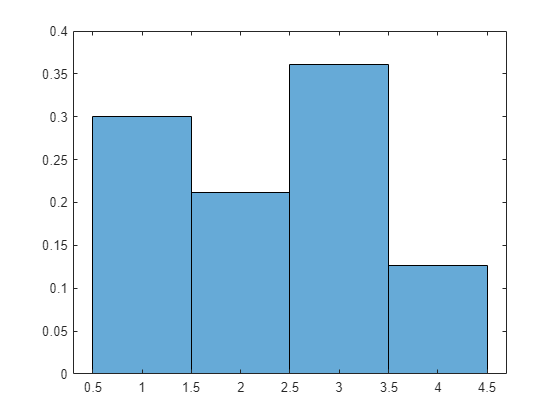

clear all; rng('default')
% to be efficient, start with the highest probability 
n = 1000;
u = rand(n,1);
x_3 = 3*(u<0.35);
x_1 = 1*(u>=0.35&u<0.65);
x_2 = 2*(u>=0.65&u<0.85);
x_4 = 4*(u>=0.85);
x = x_1+x_2+x_3+x_4;
% Then to check if it worked, we can do a histogram
histogram(x,Normalization="probability")

**Chapter 4. Question 12:**


rng('default')
n = 1e6;
mu = 0;sig = 1;
u = rand(n,1);
get_z = @(x) (x-mu)/sig;
u = get_z(u);
g = @(x) abs(x.*exp(-((x-mu).^2)./(2*sig.^2))./(sqrt(2*pi*sig.^2)));
hu = g(log(u./(1-u))).*(1./((u-u.^2))); %g(of transform)*jacobian 
Exhat = mean(hu)

Exhat = 0.7977

**Chapter 4. Question 15:**

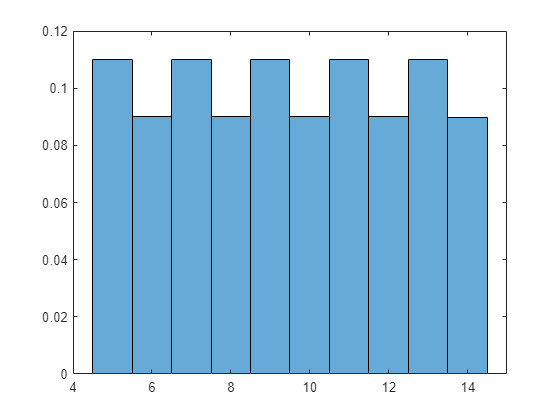

n = 1e7;
u = rand(n,1);
x_5 = 5*(u<0.11);
x_6 = 6*(u>=0.11&u<0.20);
x_7 = 7*(u>=0.20&u<0.31);
x_8 = 8*(u>=0.31&u<0.40);
x_9 = 9*(u>=0.40&u<0.51);
x_10 = 10*(u>=0.51&u<0.60);
x_11 = 11*(u>=0.60&u<0.71);
x_12 = 12*(u>=0.71&u<0.80);
x_13 = 13*(u>=0.80&u<0.91);
x_14 = 14*(u>=0.91);

x = x_5+x_6+x_7+x_8+x_9+x_10+x_11+x_12+x_13+x_14;
% Then to check if it worked, we can do a histogram
histogram(x,Normalization="probability")

**Chapter 4. Question 17:**

To solve this problem, we can use the accept/reject method. 

Using the codes from the slides and making the necessary changes 

rng('default')
max_j = 20;
x = (1:max_j);
p = (1/2).^(x+1)+(1/2.*2.^(x-1))/3.^x; % pdf

N=max_j; 
q=1/N*ones(max_j,1);
p=p';
c=max(p./q);


n=1000; nn=1000000;
X=zeros(n,1);
count=0; Y=zeros(n,1);
R=p./(c*q);
for j=1:nn
    Y(j,1)=randi([1,max_j-1]); % which integers should we generate?
    U=rand(1,1);
    if (U<=p(Y(j,1)+1,1)/(c*q(Y(j,1)+1,1)))
        count=count+1;
        X(count,1)=Y(j,1);
    end
    if (count==n)
        return;
    end
end

Then we can plot the histogram with the function to see what it looks like

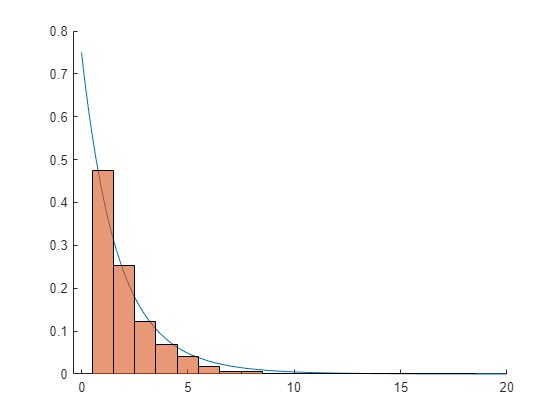

figure
hold on
f = @(x) (1/2).^(x+1)+(1/2.*2.^(x-1))./3.^x;
fplot(f,[0 max_j])
histogram(X,'Normalization','probability')